N=10;         % number of nodes
e_num=20;         % number of edges in the network
s=1;              % Initialization of source node
w=[7 1 3 2 4 8 2 1 3 4 7 6 5 2 2 3 4 2 1 5];   
m=[1 1 3 2 3 2 4 4 3 6 6 6 6 5 7 7 7 8 9 10];  
n=[2 3 2 5 5 4 2 5 6 5 7 9 8 7 4 10 9 9 10 4];  
names={'A','B','C','D','E','F','G','H','L','M'};
G=digraph(m,n,w)

G =   digraph with properties:

    Edges: [20×2 table]
    Nodes: [10×0 table]


h =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [1 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


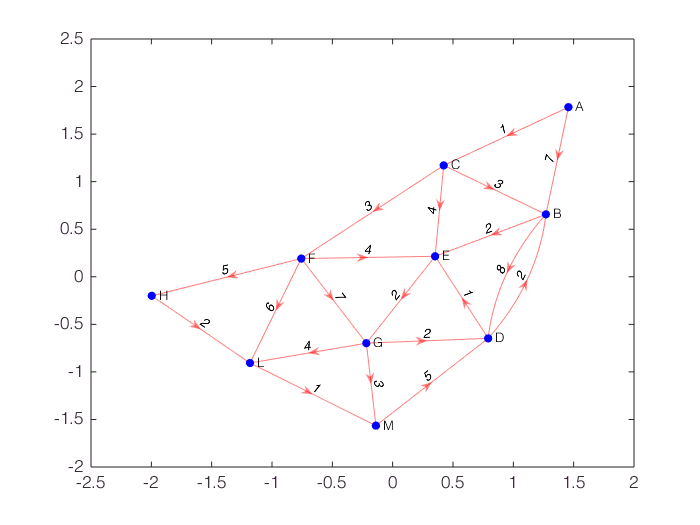

h=plot(G,'EdgeLabel',G.Edges.Weight,'Nodelabel',names,'EdgeColor','r','NodeColor','b')

[conn,cM,rD]= ImportData();
[weights numEdges] = makeWeights(cM, rD);

N=size(weights,1);         % number of nodes
weightVals = zeros(1,numEdges);
startPointVals = zeros(1,numEdges);
endPointVals = zeros(1,numEdges);
index = 1;


rawData =    200   200     0
   225   200     0
   225   222     0
   225   167     0
   243   200     0
   225   200    19
   225   222    19
   225   167    19
   243   200    19
   225   200    38


nodeLabels =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


connections =      2    18     0     0     0
     1     3     4     5     6
     2     7    20     0     0
     2     8     0     0     0
     2     9     0     0     0
     7     8     9    10     0
     6     3    11     0     0
     6     4    12     0     0
     6     5    13     0     0
    11    12    13     6    14


dataLen = 34

weights =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

G2 =   digraph with properties:

    Edges: [102×2 table]
    Nodes: [34×0 table]


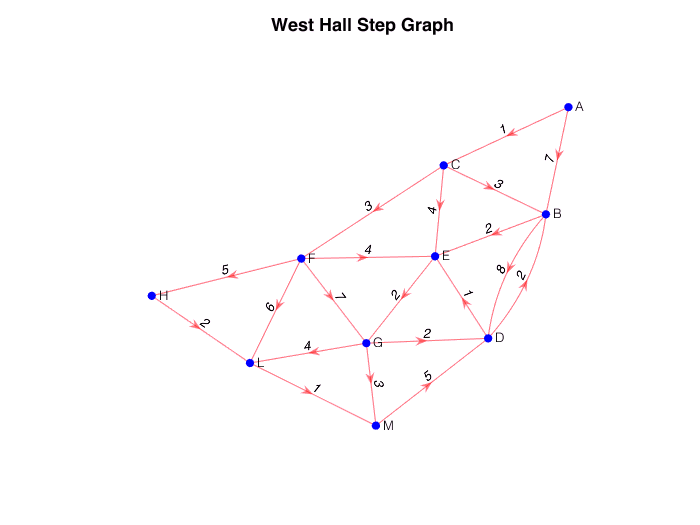

Error using matlab.graphics.chart.primitive.GraphPlot/set.NodeLabel
Expect NodeLabel input to have length 34 or to be empty.

Error in matlab.graphics.chart.primitive.GraphPlot

Error in digraph/plot (line 102)
hObj = matlab.graphics.chart.primitive.GraphPlot('BasicGraph', ...

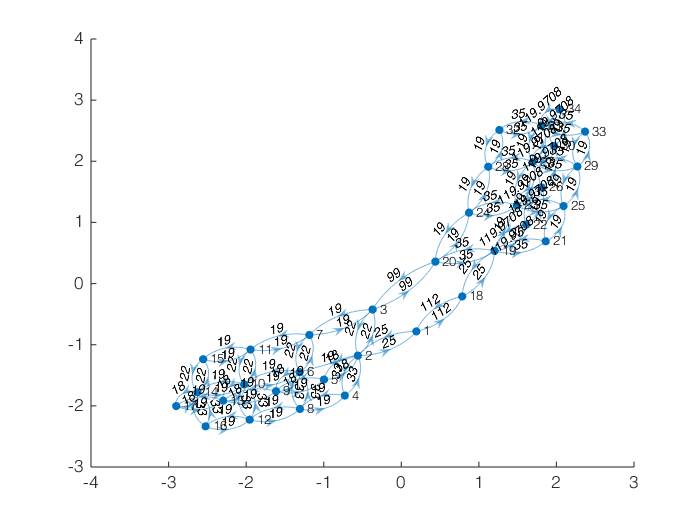


for i= 1:N
    for j = 1:N
        if(weights(i,j)~=0)
            weightVals(index) = weights(i,j);
            startPointVals(index) = i;
            endPointVals(index) = j;
            index = index + 1;
        end
    end 
end

s2=1;              % Initialization of source node
  
namesBank2={'A','B','C','D','E','F','G','H','L','M','N','O','P','Q','R','S','T', 'U', 'V', 'W', 'X', 'Y', 'Z', 'AA', 'BB','CC','DD','EE','FF','GG','HH','LL','MM','NN','OO','PP','QQ','RR','SS','TT', 'UU', 'VV', 'WW', 'XX', 'YY', 'ZZ'};
names2 = namesBank2(1:N);
G=digraph(startPointVals,endPointVals,weightVals)
title('West and East Hall Step Graph')
axis off
h2=plot(G,'EdgeLabel',G.Edges.Weight,'Nodelabel',names2,'EdgeColor','b','NodeColor','r')

masterMatrix = [startPointVals, endPointVals, weightVals];

%Setting inital distances to Inf (source node starts at 0)
dists = zeros(N);
dists(1:N) = Inf;
dists(1) = 0;
parentNodes(1:N) = 0;

for i = 1:N %For every node
    for j = 1:numEdges %For every edge
        distance = dists(startPointVals(j)); %Calculate the new distance
        if distance < dists(endPointVals(j))
            %Update the Distance
            dists(endPointVals(j)) = distance;
            parentNodes(endPointVals(j)) = startPointVals(j);
        end
    end
end

destin=input('Where do you want to go?');
totalStepsTaken = dists(destin)
path=shortestpathtree(G,1,destin);
p=plot(G,'EdgeLabel',G.Edges.Weight,'Nodelabel',names2,'EdgeColor','k','NodeColor','b')
highlight(p,path,'EdgeColor','g','LineWidth',5);






S=sparse(m',n',w')

S =    (1,2)        7
   (3,2)        3
   (4,2)        2
   (1,3)        1
   (2,4)        8
   (7,4)        2
  (10,4)        5
   (2,5)        2
   (3,5)        4
   (4,5)        1
   (6,5)        4
   (3,6)        3
   (5,7)        2
   (6,7)        7
   (6,8)        5
   (6,9)        6
   (7,9)        4
   (8,9)        2
   (7,10)       3
   (9,10)       1


distance(1:N)=Inf;   % distance of each node initialized to infinity 
distance(s)=0;             % distance of source node intitalized to 0
predecessor(1:N)=0;
for i = 1 : N - 1
    for j = 1 : e_num
      v = n(j);
      u = m(j);
      t = distance(u) + w(j);
      if (t < distance(v) )
        distance(v) = t;
        predecessor(v) = u
      end
    end
  end

predecessor =      0     1     0     0     0     0     0     0     0     0


predecessor =      0     1     1     0     0     0     0     0     0     0


predecessor =      0     3     1     0     0     0     0     0     0     0


predecessor =      0     3     1     0     2     0     0     0     0     0


predecessor =      0     3     1     0     3     0     0     0     0     0


predecessor =      0     3     1     2     3     0     0     0     0     0


predecessor =      0     3     1     2     3     3     0     0     0     0


predecessor =      0     3     1     2     3     3     6     0     0     0


predecessor =      0     3     1     2     3     3     6     0     6     0


predecessor =      0     3     1     2     3     3     6     6     6     0


predecessor =      0     3     1     2     3     3     5     6     6     0


predecessor =      0     3     1     7     3     3     5     6     6     0


predecessor =      0     3     1     7     3     3     5     6     6     7


totalCost = 9

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 5

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 4

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 7

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 9

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 10

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 10

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 4

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


totalCost = 9

p =   GraphPlot with properties:

     NodeColor: [0 0 1]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'A'  'B'  'C'  'D'  'E'  'F'  'G'  'H'  'L'  'M'}
     EdgeLabel: {'7'  '1'  '8'  '2'  '3'  '4'  '3'  '2'  '1'  '2'  '4'  '7'  '5'  '6'  '2'  '4'  '3'  '2'  '1'  '5'}
         XData: [1.4568 1.2701 0.4230 0.7914 0.3519 -0.7575 -0.2181 -1.9963 -1.1825 -0.1388]
         YData: [1.7831 0.6562 1.1709 -0.6473 0.2153 0.1913 -0.6980 -0.2002 -0.9065 -1.5649]
         ZData: [0 0 0 0 0 0 0 0 0 0]

  Show all properties


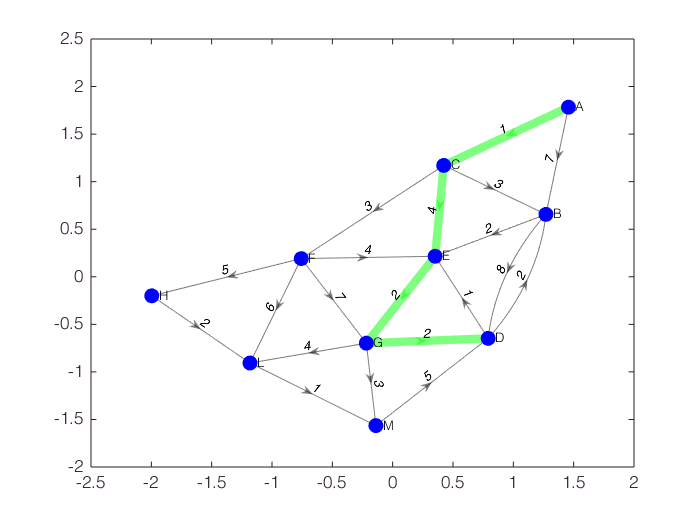

% For checking negative weight cycles
for j = 1 : e_num
    u = m(j);
    v = n(j);
    if ( distance(u) + w(j) < distance(v) )
      fprintf ( 1, '\n' );
      fprintf ( 1, 'BELLMAN_FORD - Fatal error!\n' );
      fprintf ( 1, '  Graph contains a cycle with negative weight.\n' );
      error ( 'BELLMAN_FORD - Fatal error!' );
    end
  end
for i=1:(N-1)
d=input('Please enter the destination node:');
totalCost = distance(d)
TR=shortestpathtree(G,1,d);
p=plot(G,'EdgeLabel',G.Edges.Weight,'Nodelabel',names,'EdgeColor','k','NodeColor','b')
p.MarkerSize=8;
highlight(p,TR,'EdgeColor','g','LineWidth',5);
end